We want to look at LIGO noise and creating simulation of it. 

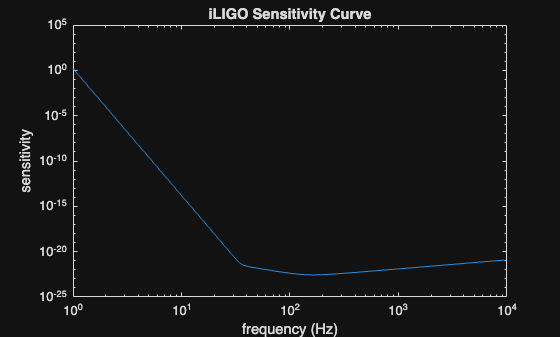

iligo = load("NOISE/iLIGOSensitivity.txt", "-ascii");
figure;
loglog(iligo(:,1),iligo(:,2));
xlabel("frequency (Hz)");
ylabel("sensitivity");
title("iLIGO Sensitivity Curve");

Next I'll use the provided PSD to generate a realization of initial ligo noise. 

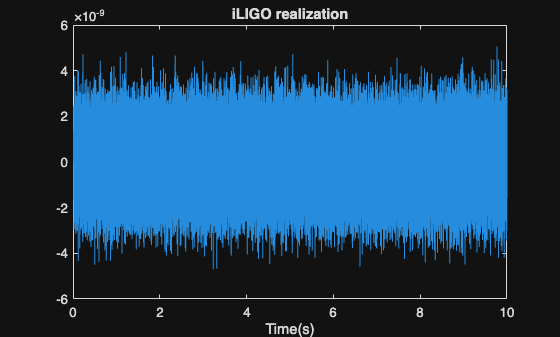

sf = 16384;
nSamples = sf * 10; % ten seconds of data
filtorder = 512;
timeVec = (0:(nSamples-1))/sf;

% we need to normalize the iligo frequency vector to follow the rule that The frequencies
% must start from 0 and end at Fs/2. 

minFreq = 50; % using theh normalizations suggested in the slides
maxFreq = 700;
nyquistFreq = sf/2;


validIdx = (iligo(:,1) >= minFreq) & (iligo(:,1) <= maxFreq);
iligoTrunc = iligo(validIdx, :);
psdstart = iligoTrunc(1, 2);   % PSD at 50 Hz
psdend = iligoTrunc(end, 2); % PSD at 700 Hz
freqExtended = [0; minFreq; iligoTrunc(:,1); maxFreq; nyquistFreq];
psdExtended = [psdstart; psdstart; iligoTrunc(:,2); psdend; psdend];
iligoExtended = [freqExtended, psdExtended];

outNoise = statgaussnoisegen(nSamples,iligoExtended,512,sf);
figure;
plot(timeVec, outNoise);
xlabel("Time(s)");
title("iLIGO realization")

Now I'm going to estimate the PSD of the generated noise and compare it to the input value

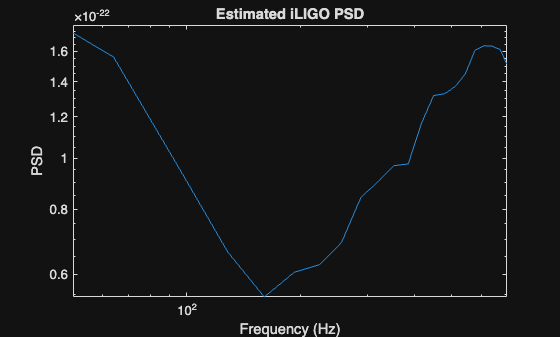

[ppx,f] = pwelch(outNoise,filtorder, [],[],sf);
figure; 
loglog(f,ppx);
xlim([50,700]); % we only want to plot in the truncated reigon, as our PSD would be different outside.
xlabel("Frequency (Hz)");
ylabel("PSD");
title("Estimated iLIGO PSD");